# Laborator 5

## Problema 1

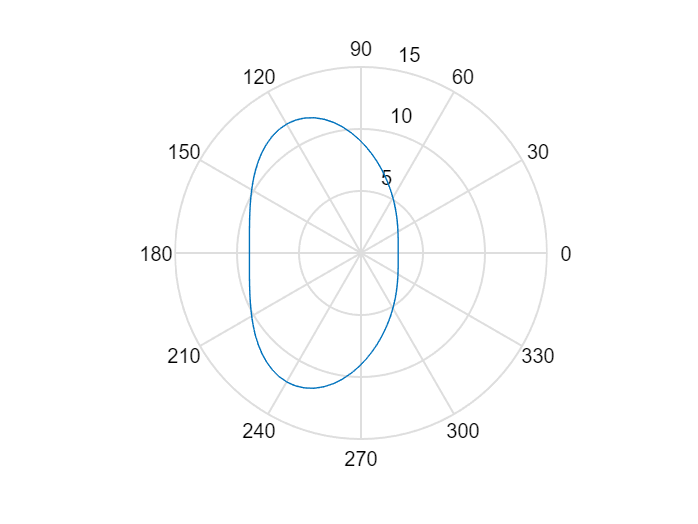

b=3; theta_0=0; theta_f=2*pi;
alpha=pi/2;
%u:=1/r

syms u(theta)

Du=diff(u);
u_eq=diff(u,theta,2)==-u+3.*sin(theta).^2/(3*b);
u_cond=u(theta_0)==1/b;
Du_cond=Du(theta_0)==-1/b*cot(alpha);
u_sol=dsolve(u_eq,[u_cond,Du_cond]);

U=matlabFunction(u_sol);
Theta=linspace(theta_0,theta_f,100);

polar(Theta, 1./U(Theta))

## Problema 2

### a)

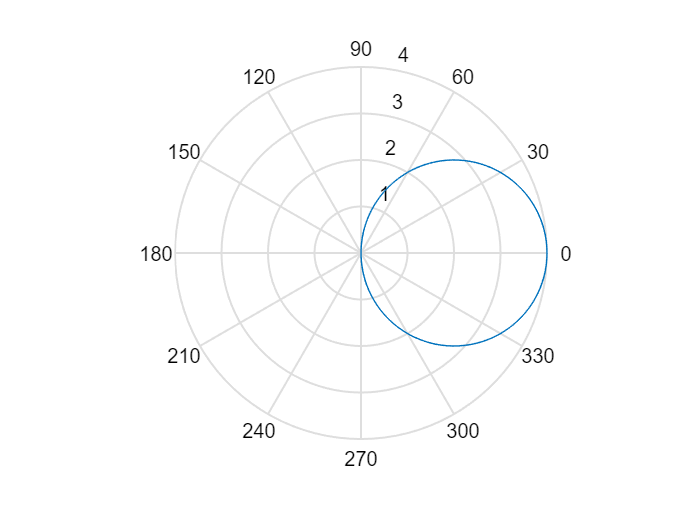

b=2; m=1; c=4*b^2; theta_0=0; theta_f=pi;
theta=linspace(theta_0,theta_f,100);
r=2*b*cos(theta);

figure(1)
polar(theta,r)

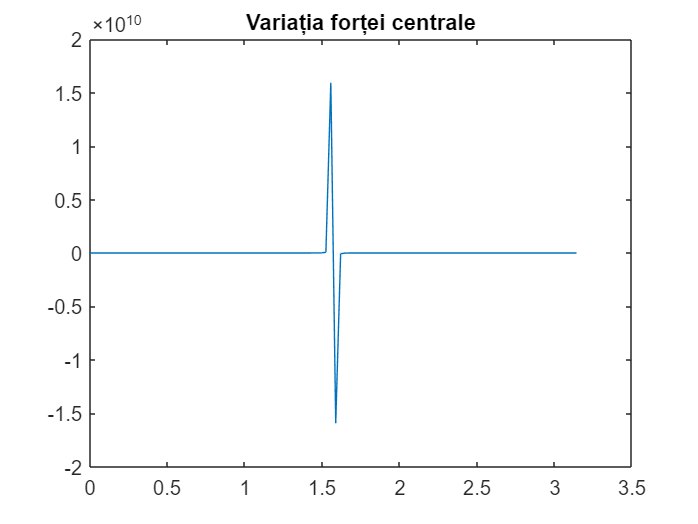

F=8*m*(c^2)*(b^3)./(r.^5);

figure(2)
plot(theta,F);
title('Variația forței centrale')

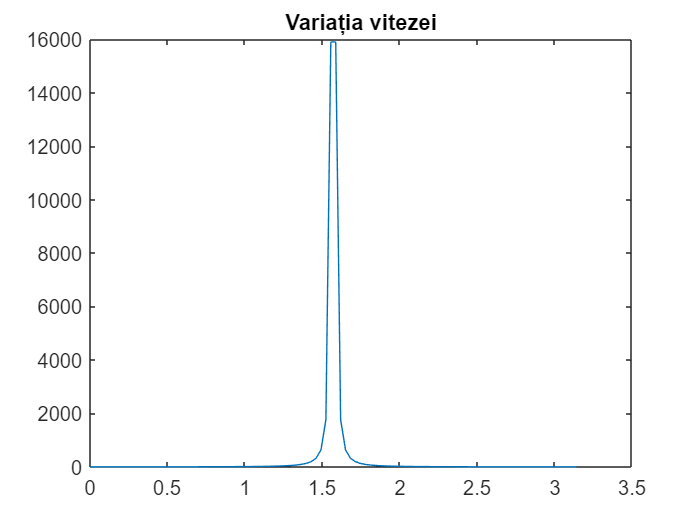

v=2*b*c./(r.^2);

figure(3)
plot(theta,v);
title('Variația vitezei')

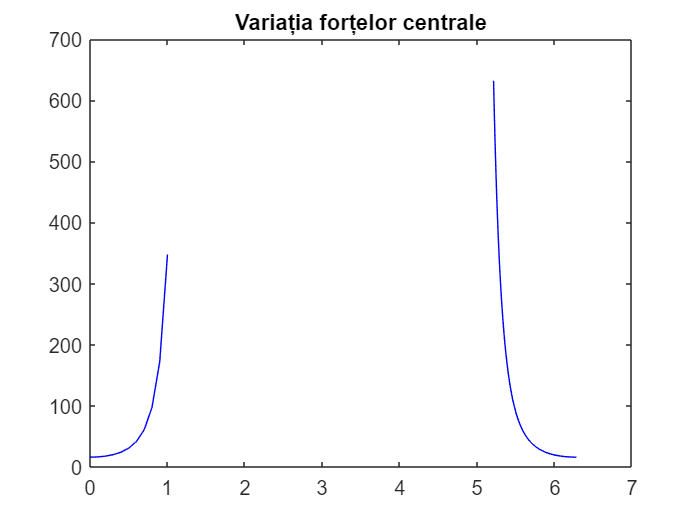

d=0.5;
T1=[0:0.1:(pi/2-d)];
T2=[(3*pi/2+d):0.01:2*pi];
R1=2*b*cos(T1); R2=2*b*cos(T2);
Forta1=8*m*(c^2)*(b^3)./(R1.^5);
Forta2=8*m*(c^2)*(b^3)./(R2.^5);

figure(4)
plot(T1,Forta1,'b',T2,Forta2,'b')
title('Variația forțelor centrale')

În acest caz, creșterea bruscă apare în jurul $\frac{\pi }{2}$, din cauză că $r$ depinde de $\cos \left(\theta \right)$. Când $M$ se află într-o vecinătate a lui $A\;$ (adică $\theta \to \frac{\pi }{2}$), $r$ tinde să fie perpendiculară pe $\textrm{Ox}$.

### b)

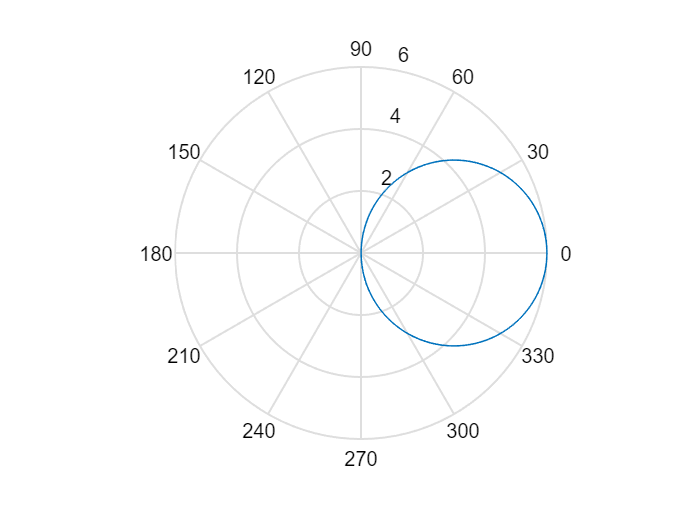

b=3; m=5; c=4*b^2; theta_0=0; theta_f=2*pi;
theta=linspace(theta_0,theta_f,100);
r=2*b*cos(theta);

figure(1)
polar(theta,r)

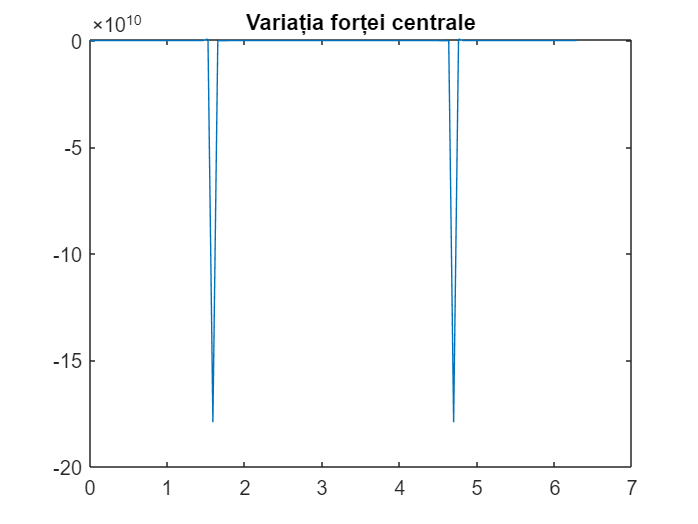

F=8*m*(c^2)*(b^3)./(r.^5);

figure(2)
plot(theta,F);
title('Variația forței centrale')

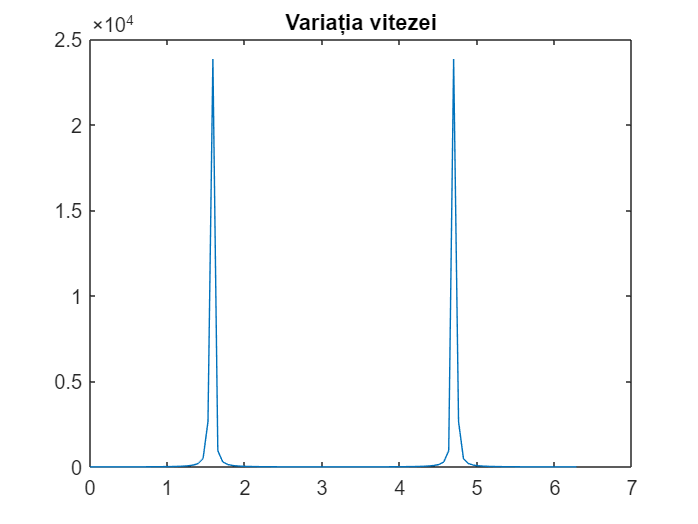

v=2*b*c./(r.^2);

figure(3)
plot(theta,v);
title('Variația vitezei')

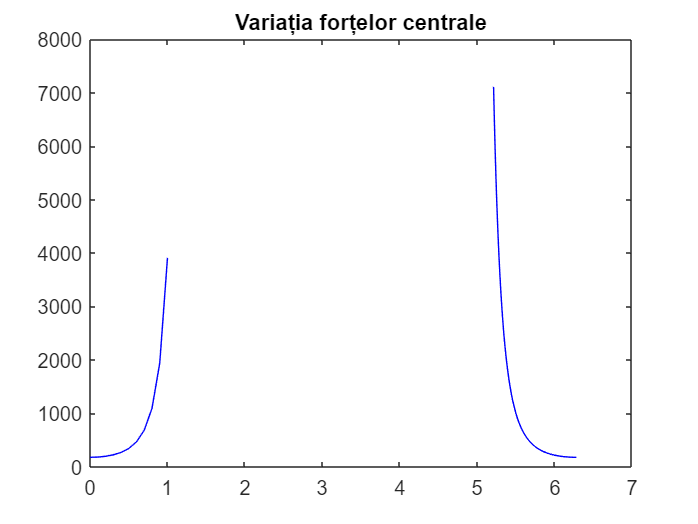

d=0.5;
T1=[0:0.1:(pi/2-d)];
T2=[(3*pi/2+d):0.01:2*pi];
R1=2*b*cos(T1); R2=2*b*cos(T2);
Forta1=8*m*(c^2)*(b^3)./(R1.^5);
Forta2=8*m*(c^2)*(b^3)./(R2.^5);

figure(4)
plot(T1,Forta1,'b',T2,Forta2,'b')
title('Variația forțelor centrale')

Justificarea este asemănătoare cu cea de la punctul a), însă creșterile bruște apar în jurul $\frac{\pi }{2}$, respectiv $\frac{3\pi }{2}$.

## Problema 3

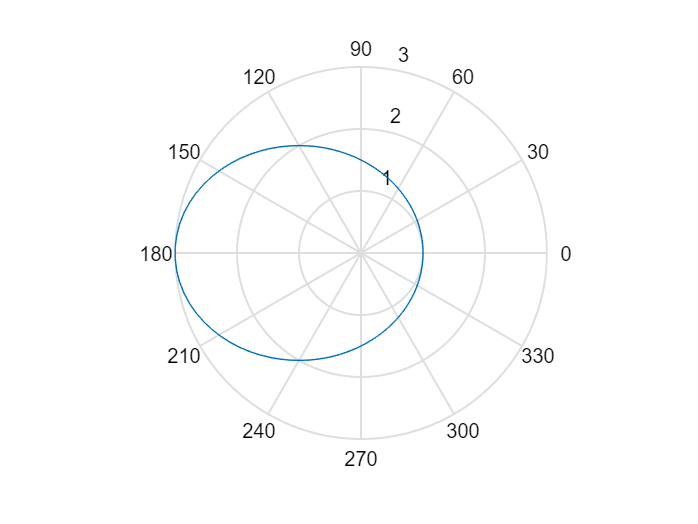

theta_0=0; theta_f=2*pi;
alpha=pi/2;
%u:=1/r

syms u(theta)

Du=diff(u);
u_eq=diff(u,theta,2)==-u+2/3;
u_cond=u(theta_0)==1;
Du_cond=Du(theta_0)==-cot(alpha);
u_sol=dsolve(u_eq,[u_cond,Du_cond]);

U=matlabFunction(u_sol);
Theta=linspace(theta_0,theta_f,100);

polar(Theta, 1./U(Theta))